%% --------------------------------------------------------------
%   Wind (Frøya) + Wave Particle Velocity Profiles (Chart Datum)
%   - Input: U_extreme (10-min extreme wind at z_CD_meas above CD)
%            Wave height H, period T, water depth h
%   - Output: Combined plot of wind profile + wave particle velocity
%             with vertical axis referenced to Chart Datum (CD)
%             and "normal" orientation (no YDir reverse).
% --------------------------------------------------------------

clear; clc; close all;

%% --------------------------------------------------------------
%  USER INPUTS
% --------------------------------------------------------------

% --- Wind inputs ---
U_extreme  = 22.82;     % extreme 10-min wind speed at measurement height (m/s)
z_CD_meas  = 20;     % measurement height above Chart Datum (m)

MSL_above_CD = 0;  % mean sea level above Chart Datum (m)
Tide         = 7.37;  % tide elevation above MSL at the time (m)


z_min_sea_wind = 0;      % minimum height above sea surface (m)
z_max_sea_wind = 50;    % maximum height above sea surface (m)
Nz_wind        = 200;


H_wave = 4.7;        % wave height H (m)
T_wave = 8.5;        % wave period T (s)
h_water = 40;       % water depth below still water level (m) from digimap
Nz_wave = 200;      % number of vertical points for wave profile

g = 9.81;           % gravity (m/s^2)

%% --------------------------------------------------------------
%  STEP 0 – Sea surface elevation relative to CD
% --------------------------------------------------------------
% eta = sea surface elevation above Chart Datum (can be positive or negative)
eta = MSL_above_CD + Tide;      

% Convert measurement height from CD -> height above sea surface
z_meas_sea = z_CD_meas - eta;   

fprintf('Sea surface elevation above CD (eta)         = %.3f m\n', eta);

Sea surface elevation above CD (eta)         = 7.370 m


fprintf('Measurement height above sea surface (z_meas) = %.3f m\n', z_meas_sea);

Measurement height above sea surface (z_meas) = 12.630 m





if z_meas_sea <= 0
    warning('Measurement point is at or below sea surface (z_meas = %.2f m).', z_meas_sea);
end

H  = 10;          % reference height for Frøya (m)
T0 = 1.0;         % hours
T_meas = 10/60;   % 10 minutes in hours

U_T_meas = U_extreme;    % your 10-min mean at z_meas_sea

% Initial guess for U0 = 1-hour mean at 10 m
U0 = U_T_meas;

for i = 1:100
    % Coefficients based on current U0
    C  = 5.73e-2 * sqrt(1 + 0.148 * U0);
    Iv = 0.06 * (1 + 0.043 * U0) * (z_meas_sea / H)^(-0.22);

    % Frøya prediction at (T_meas, z_meas)
    factor = (1 + C * log(z_meas_sea / H)) * ...
             (1 - 0.41 * Iv * log(T_meas / T0));

    % Fixed-point update for U0
    U0_new = U_T_meas / factor;

    if abs(U0_new - U0) < 1e-6
        break;
    end

    U0 = U0_new;
end
fprintf('1-hour mean wind speed at 10 m above sea level (U0) = %.3f m/s\n', U0);

1-hour mean wind speed at 10 m above sea level (U0) = 20.596 m/s



% Height of that 10 m point relative to Chart Datum
z10_CD = H + eta;




%% --------------------------------------------------------------
%  STEP 3 – Generate Frøya wind profile (above sea surface)
% --------------------------------------------------------------
z_sea_wind = linspace(z_min_sea_wind, z_max_sea_wind, Nz_wind);  % heights above sea surface

C = 0.0573 * sqrt(1 + 0.148 * U0);
U_wind =U0 .* (1 + C .* log(z_sea_wind ./ (z_CD_meas-Tide)))*(1 - 0.41 * Iv * log(T_meas / T0));

% Convert wind profile heights to Chart Datum reference
z_CD_wind = z_sea_wind + eta;  % height above CD


% The value used for wave prediction 
u_wind_10m = U0 .* (1 + C .* log(10 ./ (z_CD_meas-Tide)))*(1 - 0.41 * Iv * log(T_meas / T0))

u_wind_10m = 21.6236

 


%% --------------------------------------------------------------
%  STEP 4 – Wave particle horizontal velocity profile (linear theory)
% --------------------------------------------------------------
% z_sea_wave: from seabed (-h) to still water level (0), relative to SWL
z_sea_wave = linspace(-h_water-eta, 0, Nz_wave);


d= h_water+eta 

d = 47.3700



% Solve dispersion relation: omega^2 = g k tanh(k h)
L = g*T_wave^2/(2*pi);   % initial guess
for i = 1:100
    L = g*T_wave^2 / (2*pi)*tanh(2*pi*d/L);
end

a = H_wave / 2;    % wave amplitude

% Maximum horizontal particle velocity:

u_wave = a * g*T_wave/L.* cosh(2*pi * (z_sea_wave + d)/L) ./ cosh(2*pi*d/L);

% Particle acceleration

a_wave = g*pi*H_wave/L.* cosh(2*pi * (z_sea_wave + d)/L) ./ cosh(2*pi*d/L)

a_wave =     0.1798    0.1798    0.1798    0.1799    0.1800    0.1802    0.1803    0.1805    0.1808    0.1811    0.1814    0.1817    0.1821    0.1825    0.1829    0.1834    0.1839    0.1844    0.1850    0.1856    0.1862    0.1869    0.1876    0.1883    0.1891    0.1899    0.1908    0.1916    0.1925    0.1935    0.1944    0.1955    0.1965    0.1976    0.1987    0.1999    0.2010    0.2023    0.2035    0.2048    0.2061    0.2075    0.2089    0.2104    0.2119    0.2134    0.2149    0.2165    0.2182    0.2198



% Convert wave depths to Chart Datum reference
z_CD_wave = z_sea_wave + eta;   % (z relative SWL) + eta -> relative to CD






%  STEP 5 – PLOT wind induced profile

vc_wind_0= U0*0.03

vc_wind_0 = 0.6179

z_wind_current = linspace(-d, 0, Nz_wave);
vc_wind = vc_wind_0*((50+z_wind_current)/50)

vc_wind =     0.0325    0.0354    0.0384    0.0413    0.0443    0.0472    0.0501    0.0531    0.0560    0.0590    0.0619    0.0649    0.0678    0.0707    0.0737    0.0766    0.0796    0.0825    0.0854    0.0884    0.0913    0.0943    0.0972    0.1002    0.1031    0.1060    0.1090    0.1119    0.1149    0.1178    0.1207    0.1237    0.1266    0.1296    0.1325    0.1355    0.1384    0.1413    0.1443    0.1472    0.1502    0.1531    0.1560    0.1590    0.1619    0.1649    0.1678    0.1708    0.1737    0.1766


z_CD_wind_current = z_wind_current + eta

z_CD_wind_current =   -40.0000  -39.7620  -39.5239  -39.2859  -39.0478  -38.8098  -38.5718  -38.3337  -38.0957  -37.8576  -37.6196  -37.3816  -37.1435  -36.9055  -36.6674  -36.4294  -36.1914  -35.9533  -35.7153  -35.4772  -35.2392  -35.0012  -34.7631  -34.5251  -34.2870  -34.0490  -33.8110  -33.5729  -33.3349  -33.0968  -32.8588  -32.6208  -32.3827  -32.1447  -31.9066  -31.6686  -31.4306  -31.1925  -30.9545  -30.7164  -30.4784  -30.2404  -30.0023  -29.7643  -29.5262  -29.2882  -29.0502  -28.8121  -28.5741  -28.3360



%  STEP 6 – PLOT tide current profile

vc_tide_0 = 1.5/((d-18)/d)^(1/7)

vc_tide_0 = 1.6060

z_tide_current = linspace(-d, 0, Nz_wave);
vc_tide = vc_tide_0*(((d+z_tide_current)/d).^(1/7))

vc_tide =          0    0.7539    0.8324    0.8821    0.9191    0.9488    0.9739    0.9956    1.0147    1.0320    1.0476    1.0620    1.0753    1.0876    1.0992    1.1101    1.1204    1.1301    1.1394    1.1482    1.1567    1.1647    1.1725    1.1800    1.1872    1.1941    1.2008    1.2073    1.2136    1.2197    1.2256    1.2314    1.2370    1.2424    1.2477    1.2529    1.2580    1.2629    1.2677    1.2724    1.2770    1.2816    1.2860    1.2903    1.2946    1.2987    1.3028    1.3068    1.3107    1.3146


z_CD_tide_current = z_tide_current + eta

z_CD_tide_current =   -40.0000  -39.7620  -39.5239  -39.2859  -39.0478  -38.8098  -38.5718  -38.3337  -38.0957  -37.8576  -37.6196  -37.3816  -37.1435  -36.9055  -36.6674  -36.4294  -36.1914  -35.9533  -35.7153  -35.4772  -35.2392  -35.0012  -34.7631  -34.5251  -34.2870  -34.0490  -33.8110  -33.5729  -33.3349  -33.0968  -32.8588  -32.6208  -32.3827  -32.1447  -31.9066  -31.6686  -31.4306  -31.1925  -30.9545  -30.7164  -30.4784  -30.2404  -30.0023  -29.7643  -29.5262  -29.2882  -29.0502  -28.8121  -28.5741  -28.3360


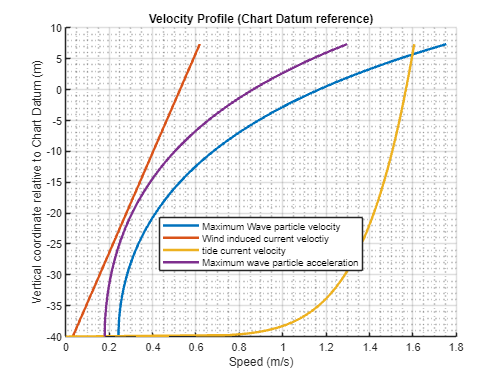



%% --------------------------------------------------------------
%  STEP 7 – PLOT combined profiles 
% --------------------------------------------------------------
figure;
hold on;

     % wind profile
plot(u_wave, z_CD_wave, 'LineWidth', 2);       % wave particle velocity profile
plot(vc_wind, z_CD_wind_current, 'LineWidth', 2);
plot(vc_tide, z_CD_tide_current, 'LineWidth', 2);
plot(a_wave, z_CD_wave, 'LineWidth', 2);



hold off;

xlabel('Speed (m/s)');
ylabel('Vertical coordinate relative to Chart Datum (m)');
title('Velocity Profile (Chart Datum reference)');

% IMPORTANT: no YDir reverse here – heights increase upward,
% so this is "upside down" compared with the earlier reversed plots.
% (CD = 0; sea surface ≈ eta; above that wind, below that wave motion.)

grid on;
legend({'Maximum Wave particle velocity', 'Wind induced current veloctiy','tide current velocity', 'Maximum wave particle acceleration'}, ...
       'Location', 'best');
set(gca, 'FontSize', 9);

grid minor;





Total_current = vc_tide + vc_wind

Total_current =     0.0325    0.7894    0.8708    0.9234    0.9633    0.9960    1.0240    1.0487    1.0708    1.0909    1.1095    1.1268    1.1430    1.1584    1.1729    1.1867    1.1999    1.2126    1.2248    1.2366    1.2480    1.2590    1.2697    1.2801    1.2903    1.3002    1.3098    1.3192    1.3285    1.3375    1.3464    1.3551    1.3636    1.3720    1.3803    1.3884    1.3964    1.4042    1.4120    1.4197    1.4272    1.4347    1.4420    1.4493    1.4565    1.4636    1.4706    1.4776    1.4844    1.4912


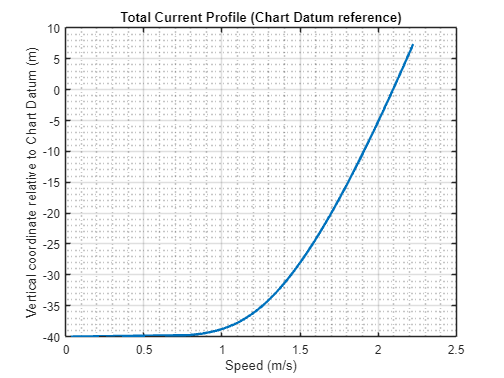

figure;
plot(Total_current, z_CD_tide_current, 'LineWidth', 2);
xlabel('Speed (m/s)');
ylabel('Vertical coordinate relative to Chart Datum (m)');
title('Total Current Profile (Chart Datum reference)');
grid on;
grid minor;

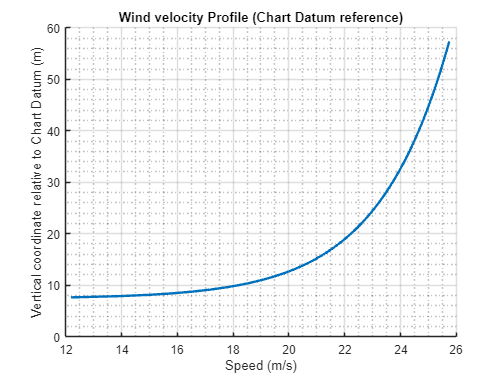




figure;
hold on
plot(U_wind, z_CD_wind, 'LineWidth', 2);


xlabel('Speed (m/s)');
ylabel('Vertical coordinate relative to Chart Datum (m)');
title('Wind velocity Profile (Chart Datum reference)');
grid on;
grid minor;



u_wave, z_CD_wave, a_wave, z_CD_wave

u_wave =     0.2432    0.2432    0.2433    0.2434    0.2435    0.2437    0.2440    0.2442    0.2446    0.2449    0.2454    0.2458    0.2463    0.2469    0.2475    0.2481    0.2488    0.2495    0.2503    0.2511    0.2519    0.2528    0.2538    0.2548    0.2558    0.2569    0.2581    0.2592    0.2605    0.2617    0.2631    0.2644    0.2658    0.2673    0.2688    0.2704    0.2720    0.2736    0.2753    0.2771    0.2789    0.2807    0.2826    0.2846    0.2866    0.2887    0.2908    0.2929    0.2951    0.2974


z_CD_wave =   -40.0000  -39.7620  -39.5239  -39.2859  -39.0478  -38.8098  -38.5718  -38.3337  -38.0957  -37.8576  -37.6196  -37.3816  -37.1435  -36.9055  -36.6674  -36.4294  -36.1914  -35.9533  -35.7153  -35.4772  -35.2392  -35.0012  -34.7631  -34.5251  -34.2870  -34.0490  -33.8110  -33.5729  -33.3349  -33.0968  -32.8588  -32.6208  -32.3827  -32.1447  -31.9066  -31.6686  -31.4306  -31.1925  -30.9545  -30.7164  -30.4784  -30.2404  -30.0023  -29.7643  -29.5262  -29.2882  -29.0502  -28.8121  -28.5741  -28.3360


a_wave =     0.1798    0.1798    0.1798    0.1799    0.1800    0.1802    0.1803    0.1805    0.1808    0.1811    0.1814    0.1817    0.1821    0.1825    0.1829    0.1834    0.1839    0.1844    0.1850    0.1856    0.1862    0.1869    0.1876    0.1883    0.1891    0.1899    0.1908    0.1916    0.1925    0.1935    0.1944    0.1955    0.1965    0.1976    0.1987    0.1999    0.2010    0.2023    0.2035    0.2048    0.2061    0.2075    0.2089    0.2104    0.2119    0.2134    0.2149    0.2165    0.2182    0.2198


z_CD_wave =   -40.0000  -39.7620  -39.5239  -39.2859  -39.0478  -38.8098  -38.5718  -38.3337  -38.0957  -37.8576  -37.6196  -37.3816  -37.1435  -36.9055  -36.6674  -36.4294  -36.1914  -35.9533  -35.7153  -35.4772  -35.2392  -35.0012  -34.7631  -34.5251  -34.2870  -34.0490  -33.8110  -33.5729  -33.3349  -33.0968  -32.8588  -32.6208  -32.3827  -32.1447  -31.9066  -31.6686  -31.4306  -31.1925  -30.9545  -30.7164  -30.4784  -30.2404  -30.0023  -29.7643  -29.5262  -29.2882  -29.0502  -28.8121  -28.5741  -28.3360


Cd = 1; Cm = 2

Cm = 2

H = ''
D = ''


D =

  0×0 empty char array



H2 = H-H1-5
H1 = sqrt(3)/2*(D-15)


H1 =

     []



H_water = linespace ()

rho_water = 1000 
F_I = rho_water*PI/4*Cm*a_wave*


